# Time axis operations

In this exercise you will see operations on 1D signals that only affect the time axis. In all cases, the amplitude values remain unchanged while their position is modified.

% Clear workspace and command window
clear;
clc;

## Sine signal

### Unit-frequency sine signal

You can use the command [sin](https://uk.mathworks.com/help/matlab/ref/sin.html) to generate a simple sine wave.

The custom function `gen_sin` generates and visualizes an analog and digital sine signal. The code for the function can be found at the end of the script (see section *Helper functions*).

Keeping the sine frequency at 1 results in an unit-frequency sine wave.

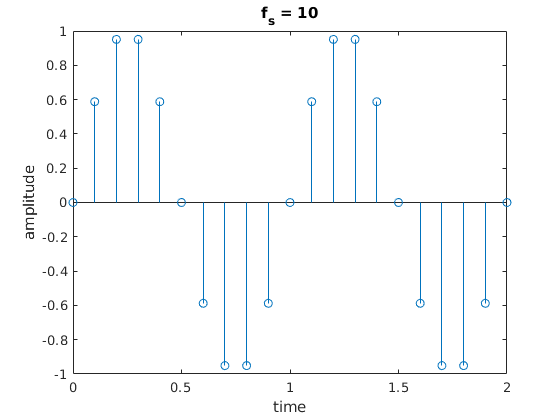

clear;clc;
fs = 10; % sampling frequency
D = 2;   % duration in seconds
[signal, n] = gen_sin(fs, D);  % unit frequency sine (i.e. 1 cycle per second)

## Time shift

Shift the signal samples by a constant value.

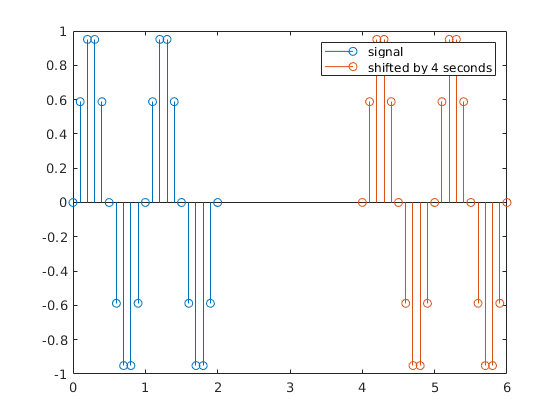

shift = 4; % set the constant
n_shifted = n + shift; % sum the constant

% Visualization
figure;
stem(n, signal);
hold on;
stem(n_shifted, signal);
hold off;
legend('signal', sprintf('shifted by %d seconds', shift));

## Reflection

Change the sign of the time instants.

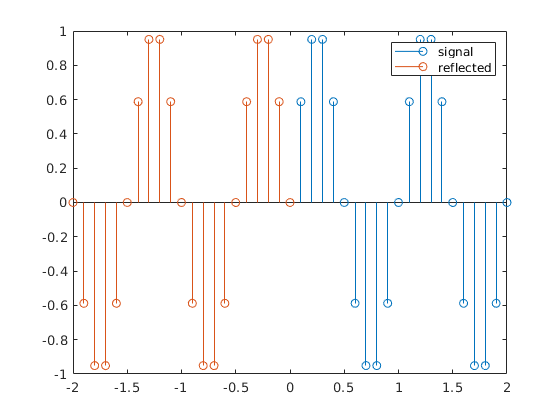

n_reflected = -n; % invert the time axis

% Visualization
figure;
stem(n, signal);
hold on;
stem(n_reflected, signal);
hold off;
legend('signal', 'reflected');

## Time scaling

Multiply or divide the time instants by a constant greater than 1.

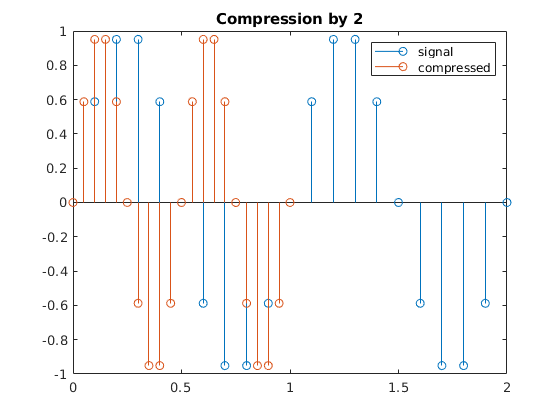

scale_factor = 2; % set a positive constant greater than or equal to 1
n_compressed = n / scale_factor;    % divide to downscale
n_expanded = n * scale_factor;     % multiply to upscale

% Visualization of downscaled signal
figure;
stem(n, signal);
hold on;
stem(n_compressed, signal);
hold off;
legend('signal', 'downscaled');
title(sprintf('Compression by %d', scale_factor));

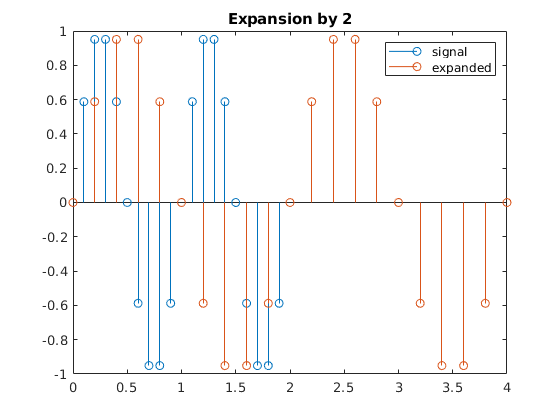


% Visualization of upscaled signal
figure;
stem(n, signal);
hold on;
stem(n_expanded, signal);
hold off;
legend('signal', 'upscale');
title(sprintf('Expansion by %d', scale_factor));

Note:

- These operations also change the sample frequency, whereas when these operations are used in real-world applications the sampling frequency is conserved.

- Reflection is a particular case of compression/expansion.

## Sub-sampling and over-sampling with zero filling

Select a subset of samples or insert new ones, whose amplitude value is set to zero.

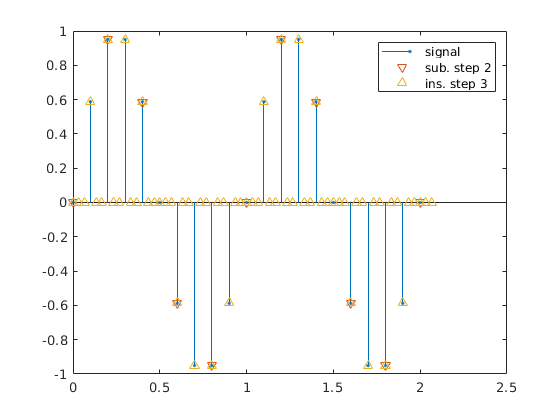

subsampling_factor =2; % sub-sampling factor
insertion_factor =3; % over-sampling factor

% Sub-sample: pick one sample over "sub_"
signal_sub = signal(1:subsampling_factor:end); % sub-sampling the amplitude array
n_sub = n(1:subsampling_factor:end);           % sub-sampling the time array
% Over-sampling: put "ins_" zeros after each sample
signal_ins = zeros(numel(signal)*insertion_factor,1);  % define the amplitude array of zeros
signal_ins(1:insertion_factor:end) = signal;           % copy the signal amplitude vector
n_expanded = zeros(numel(signal)*insertion_factor,1);       % define the time array of zeros
for i=1:insertion_factor
    % Fill the time array with values
    % For i equals 1, original time array is copied
    n_expanded(i:insertion_factor:end) = n + (i-1)/fs/insertion_factor; % compute the time values
end

% Visualization
figure;
stem(n,signal,'.');
hold on;
scatter(n_sub,signal_sub,'v');
scatter(n_expanded,signal_ins,'^');
hold off;
legend('signal', ...
    sprintf('sub-s. step %d', subsampling_factor), ...
    sprintf('over-s. step %d', insertion_factor));

Note:

- These operations are combined with a carefully choosen low-pass filter to produce decimation and oversampling.

- Both these two operations change the number of samples.

## Helper functions

### Generate and visualize a sine signal

Samples a sinusoid with frequency equals to 1. This is achieved by using the [sin](https://uk.mathworks.com/help/matlab/ref/sin.html) function.

Inputs:

- `fs`: sampling frequency

- `D`: duration of total signal

- `plot_fig`: boolean flag [defaut: true]

Outputs:

- `signal`: y-values of the digital signal

- `n`: x-values of the digital signal

function [signal, n] = gen_sin(fs, D, plot_fig)
if nargin<3 || isempty(plot_fig), plot_fig=true; end
n = (0:1/fs:D)';      % temporal axis
signal = sin(2*pi*n); % samples

if plot_fig
    % Visualization
    figure; stem(n,signal);
    xlabel('time'); ylabel('amplitude');
    title(sprintf('f_s = %g', fs));
end
end